close all

%% SIGNAL GENERATION
clearvars
DEBUG = false;
powerReduce = 5

powerReduce = 5

dopplerStart = 45.52

dopplerStart = 45.5200

dopplerEnd = dopplerStart + 5

dopplerEnd = 50.5200

signalDirectory = "binData/tempTest"

signalDirectory = "binData/tempTest"

testSignalName =  "T_tempTest"

testSignalName = "T_tempTest"

TESTPARS = struct("name",testSignalName, ...
                  "dstart",dopplerStart, ...
                  "dend",dopplerEnd, ...
                  "deveryChip",true, ...
                  "dmode",1, ...
                  "envelope",1, ...
                  "envelopePhase",0,...
                  "inNoise",1, ...
                  "outNoise",1, ...
                  "outNoise_Length",1223, ...
                  "outBits_Length",7, ...
                  "outPRN_Length",45, ...
                  "powerReduce",powerReduce);
generateTestSignal

ans = "Generation test signal completed."

pause(0.5)

%% RECEIVER SIMULATION
clearvars
DEBUG = true;
outDirectory = "outData/tempTest"

outDirectory = "outData/tempTest"

settingsName = "settings.ini"

settingsName = "settings.ini"

resultsName = "test000000.json"

resultsName = "test000000.json"

signalDirectory = "binData/tempTest"

signalDirectory = "binData/tempTest"

testSignalName =  "T_tempTest.bin"

testSignalName = "T_tempTest.bin"


preciseInterval = 281650

preciseInterval = 281650

filterBandMultiplier = 1

filterBandMultiplier = 1

reducedMaxDoppler = 100 %comment to search on the full interval...

reducedMaxDoppler = 100

nTestedDoppler = 100 %... but test more frequencies to keep the same resolution

nTestedDoppler = 100

thresholdSTD = 3 %correct threshold for tracking = 3/4

thresholdSTD = 3

ppSegmentSize = 10

ppSegmentSize = 10

nCoherentFractions = 1

nCoherentFractions = 1

ans = "Acquisition search 10.0% completed."

ans = "Acquisition search 20.0% completed."

ans = "Acquisition search 30.0% completed."

ans = "Acquisition search 40.0% completed."

ans = "Acquisition search 50.0% completed."

ans = "Acquisition search 60.0% completed."

ans = "Acquisition search 70.0% completed."

ans = "Acquisition search 80.0% completed."

ans = "Acquisition search 90.0% completed."

ans = "Acquisition search 100.0% completed."

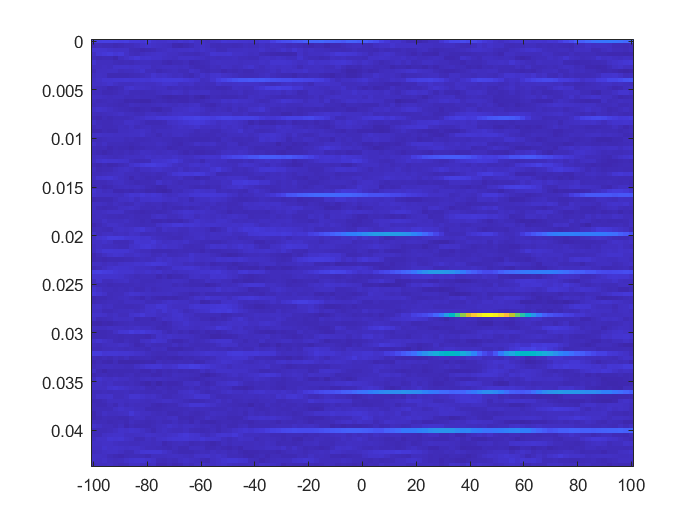

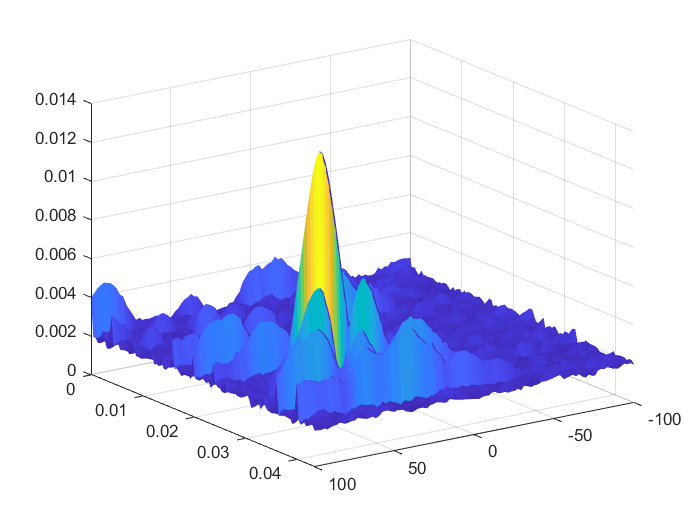

ans = struct with fields:
           maxPeak: 0.0137
       idStartTime: 281652
    idDopplerShift: 74
              mean: 1.3038e-07
        meanSquare: 1.0120e-06
             phase: 1.7561


ans = "Tracker step 1: demodulated 10 symbols."

  115.8530



ans = "Tracker step 2: demodulated 20 symbols."

  107.7319



ans = "Tracker step 3: demodulated 30 symbols."

  290.5029



ans = "Tracker step 4: demodulated 40 symbols."

  284.4102



ans = "Tracker step 5: demodulated 50 symbols."

  213.6194



ans = "Tracker step 6: demodulated 60 symbols."

  138.4855



ans = "Tracker step 7: demodulated 70 symbols."

  280.2083



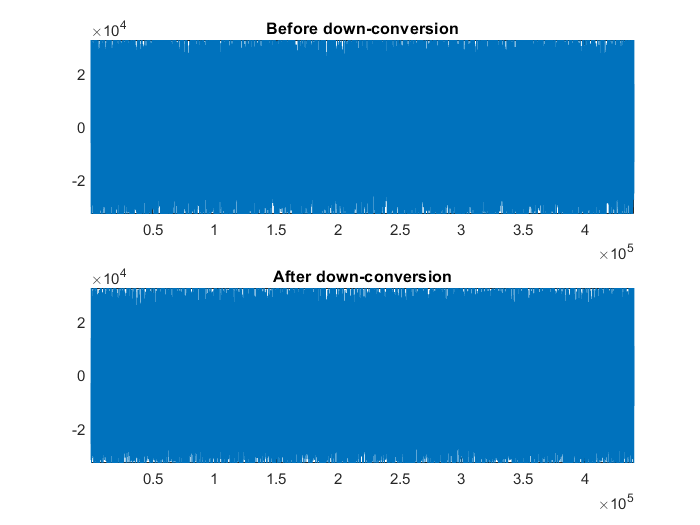

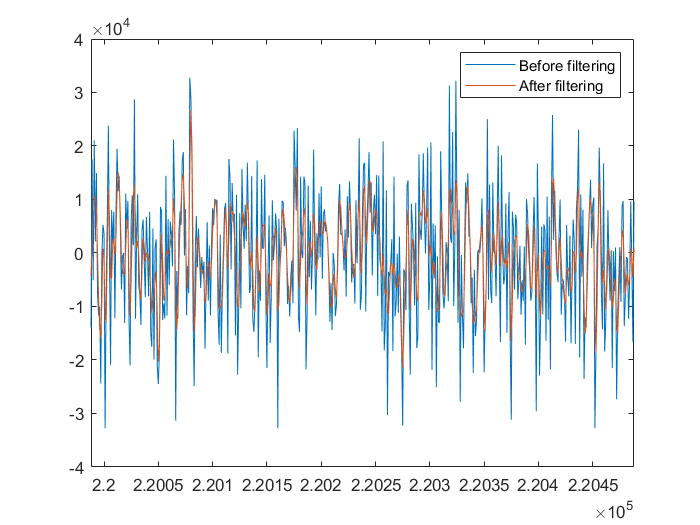

ans = "Tracker step 8: demodulated 80 symbols."

  172.2300



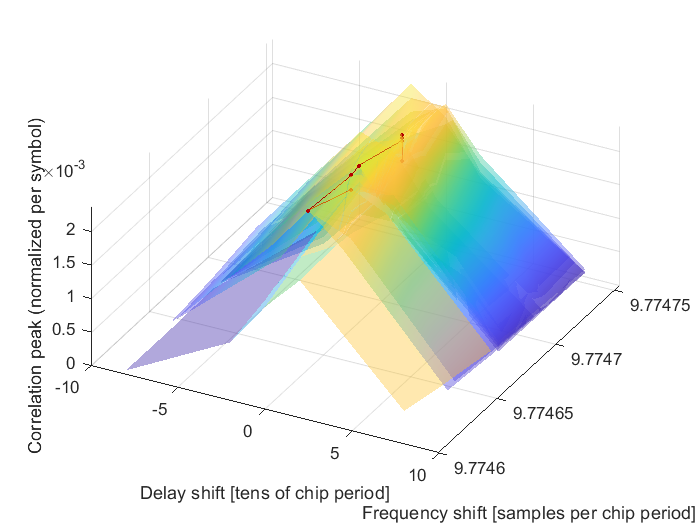

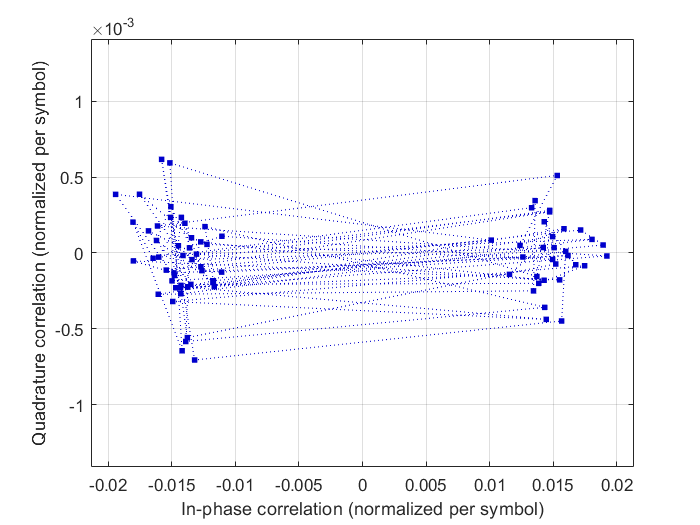

ans = "Received message analyzed."

ans = "DEMODULATION RESULT 1"

ans = struct with fields:
                  version: "2"
           ACQUISITION_OK: 1
              TRACKING_OK: 1
          DEMODULATION_OK: 1
                    SV_ID: '000001'
               message_ID: '0011'
             message_body: '010100110001110011001011101110'
                      CRC: '000110111100100010100001'
                    ACKed: 1
             isACKmessage: 1
    estimatedDopplerStart: 47.4747
      estimatedDopplerEnd: 52.0040
           estimatedDelay: 0.0282
           estimatedPhase: 1.7562


ans = "Results saved in test000000_220608_183148.json"


if filterBandMultiplier == 1
    filAttenuation_dB_dec = 390;
elseif filterBandMultiplier == 3
    filAttenuation_dB_dec = 2900;
end

RECEIVER


%clearvars